%%%%%% By: UNSW 杨雨新 3107626346@qq.com 
clear all;
syms Ls Rco Co RL  Ce positive
syms vc positive
syms s 
syms Ri positive
syms Re
Ze = Re*(1/(s*Ce))/(Re+1/(s*Ce));
ZRLC = s*Ls+RL*(Rco+1/(s*Co))/(RL+(Rco+1/(s*Co)));
tf_il_vc = Ze/(Ze+ZRLC)/Ri;
tf_il_vc = collect(simplify(expand(tf_il_vc)),s)

$$tf\_il\_vc = \frac{\left(\mathrm{Co}\,\mathrm{RL}\,\Re+\mathrm{Co}\,\mathrm{Rco}\,\Re\right)\,s+\Re}{\left(\mathrm{Ce}\,\mathrm{Co}\,\mathrm{Ls}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Co}\,\mathrm{Ls}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}\right)\,s^{3}+\left(\mathrm{Co}\,\mathrm{Ls}\,\mathrm{RL}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Ls}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{Ls}\,\mathrm{Rco}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}\right)\,s^{2}+\left(\mathrm{Ls}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}\right)\,s+\mathrm{RL}\,\mathrm{Ri}+\Re\,\mathrm{Ri}}$$

tf_vo_vc = collect (simplify(expand(tf_il_vc*parallelz(RL,Rco+1/(s*Co)))),s)

$$tf\_vo\_vc = \frac{\left(\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\Re\right)\,s+\mathrm{RL}\,\Re}{\left(\mathrm{Ce}\,\mathrm{Co}\,\mathrm{Ls}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Co}\,\mathrm{Ls}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}\right)\,s^{3}+\left(\mathrm{Co}\,\mathrm{Ls}\,\mathrm{RL}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Ls}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{Ls}\,\mathrm{Rco}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}\right)\,s^{2}+\left(\mathrm{Ls}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}\right)\,s+\mathrm{RL}\,\mathrm{Ri}+\Re\,\mathrm{Ri}}$$

%% 1) 提取分子与分母（使 tf = N/D）
[N,D] = numden(tf_il_vc);
N = expand(N);
D = expand(D);

%% 显示（可选）
disp('Numerator N(s) ='); pretty(N)

Numerator N(s) =
Re + Co RL Re s + Co Rco Re s



disp('Denominator D(s) ='); pretty(D)

Denominator D(s) =
                                                                                                         2                2                 2                       2                      3                       3
RL Ri + Re Ri + Ls Ri s + Ce RL Re Ri s + Co RL Rco Ri s + Co RL Re Ri s + Co Rco Re Ri s + Co Ls RL Ri s  + Ce Ls Re Ri s  + Co Ls Rco Ri s  + Ce Co RL Rco Re Ri s  + Ce Co Ls RL Re Ri s  + Ce Co Ls Rco Re Ri s




%% 2) 把 D(s) 化为关于 s 的多项式（清除 D 中系数上的分母）
% D 可能仍含诸如 1/Co 等形式或者更内层的分式：对 D 再做 numden，
% 得到 D = Dnum/Dden，其中 Dnum 是关于 s 的多项式（系数可能含参数），
% Dden 与参数有关但不含 s（或者是关于 s 的低阶分母）。极点由 Dnum==0 决定。
[Dnum, Dden] = numden(D);
polyD = expand(Dnum);    % polyD 是我们要设为 0 的多项式（关于 s）
%% 假定 polyD 已在工作区（符号多项式）
% polyD = ... ; % 你之前的 polyD

%% 1) 提取系数并确认为三阶
polyD = expand(polyD);
% 找出符号变量（通常为 s）
vars = symvar(polyD);
if isempty(vars)
    error('polyD 中不含符号变量。');
end

% 提取系数向量（最高次到常数），并检测次数
coeffs_vec = coeffs(polyD,s);   % 例如 [a3 a2 a1 a0]
deg = length(coeffs_vec)-1;
if deg ~= 3
    error('当前脚本仅用于三阶多项式 (degree==3)。 polyD 的次数 = %d', deg);
end

% 取出系数为符号量
a0 = coeffs_vec(1)

$$a0 = \mathrm{RL}\,\mathrm{Ri}+\Re\,\mathrm{Ri}$$

a1 = coeffs_vec(2)

$$a1 = \mathrm{Ls}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}$$

a2 = coeffs_vec(3)

$$a2 = \mathrm{Co}\,\mathrm{Ls}\,\mathrm{RL}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Ls}\,\Re\,\mathrm{Ri}+\mathrm{Co}\,\mathrm{Ls}\,\mathrm{Rco}\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}$$

a3 = coeffs_vec(4)

$$a3 = \mathrm{Ce}\,\mathrm{Co}\,\mathrm{Ls}\,\mathrm{RL}\,\Re\,\mathrm{Ri}+\mathrm{Ce}\,\mathrm{Co}\,\mathrm{Ls}\,\mathrm{Rco}\,\Re\,\mathrm{Ri}$$

simplify(a2*a1-a3*a0)

$$ans = {\mathrm{Ri}}^{2}\,\left(\mathrm{Co}\,\mathrm{Ls}\,\mathrm{RL}+\mathrm{Ce}\,\mathrm{Ls}\,\Re+\mathrm{Co}\,\mathrm{Ls}\,\mathrm{Rco}+\mathrm{Ce}\,\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}\,\Re\right)\,\left(\mathrm{Ls}+\mathrm{Ce}\,\mathrm{RL}\,\Re+\mathrm{Co}\,\mathrm{RL}\,\mathrm{Rco}+\mathrm{Co}\,\mathrm{RL}\,\Re+\mathrm{Co}\,\mathrm{Rco}\,\Re\right)-\mathrm{Ce}\,\mathrm{Co}\,\mathrm{Ls}\,\Re\,{\mathrm{Ri}}^{2}\,\left(\mathrm{RL}+\mathrm{Rco}\right)\,\left(\mathrm{RL}+\Re\right)$$

% solve(a2*a1-a3*a0>0,Re)



%%%%%%%%%%接下来我们尝试数值建模传函对象并尝试用sisotool 进行整定
s=tf('s');
Ls = 10e-6;
D = 0.2;
Vin = 12;
Vout = Vin*D;
Tsw = 1/100000;
f_low = 10;                % 起始频率 10 Hz
f_high = 1/(2*Tsw);        % 结束频率 = fs/2 = 1/(2*Tsw)
Rco = 10e-3;
Co = 100e-6;
RL = 1;
Ce = Tsw*Tsw/(Ls*pi*pi)

Ce = 1.0132e-06

Se = 0;
Ri = 0.1

Ri = 0.1000

Sn = (Vin-Vout)*Ri/Ls

Sn = 9.6000e+04

Sf = Vout*Ri/Ls

Sf = 2.4000e+04

Re = Ls/(Tsw*((Sn+Se)/(Sn+Sf)-0.5))

Re = 3.3333

tf_matlab=((Co*RL*Rco*Re)*s + RL*Re)/((Ce*Co*Ls*RL*Re*Ri + Ce*Co*Ls*Rco*Re*Ri)*s^3 + (Co*Ls*RL*Ri + Ce*Ls*Re*Ri + Co*Ls*Rco*Ri + Ce*Co*RL*Rco*Re*Ri)*s^2 + (Ls*Ri + Ce*RL*Re*Ri + Co*RL*Rco*Ri + Co*RL*Re*Ri + Co*Rco*Re*Ri)*s + RL*Ri + Re*Ri)


tf_matlab =
 
                  3.333e-06 s + 3.333
  ---------------------------------------------------
  3.411e-16 s^3 + 1.047e-10 s^2 + 3.51e-05 s + 0.4333
 
Continuous-time transfer function.


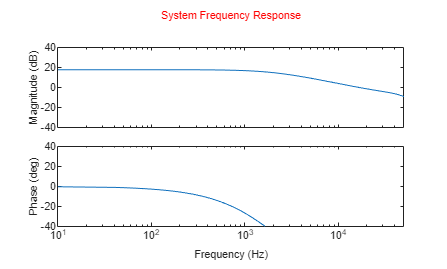

opts = bodeoptions;
opts.XLim = [f_low, f_high];
opts.YLim = [-40, 40];
opts.Title.Color = [1 0 0];
opts.Title.String = 'System Frequency Response';
opts.FreqUnits = 'Hz';
bodeplot(tf_matlab,opts);